## **Tow Thomas Biquad filter**

**Tow Thomas Filter Component values**

clear;clc;
qp = 30;
wp = (2*pi*1e3);
a0 = wp^2;
a1 = wp/qp;
b0 = wp^2;
b1 = 0;
b2 = 1;
k1 = 1;
k2 = 1;
fs = logspace(1, 5,3000);
ws = 2*pi*fs;

## **Values of Resistors and Capacitors**

C1 = 100e-9;%assumed
C2 = 100e-9;%assumed
R1 = 1/(a1*C1);
R2 = k1/(a0^0.5*C2);
R8 = 1e3;
R3 = (1/(k1*k2))*(1/(a0^0.5*C1));
R4 = 1/(k2*(b2*a1-b1)*C1);
R5 = (k1*a0^0.5)/(b0*C2);
R6 = (1/b2)*R8;
R7 = k2*R8;
X=['R1 = ',num2str(R1),' R2 = ',num2str(R2),'  R3 = ' ,num2str(R3),' R4 = ' ,num2str(R4),' R5 = ' ,num2str(R5),' R6 = ' ,num2str(R6),' R7 = ' ,num2str(R7),' R8 = ' ,num2str(R8),' C1 = ' ,num2str(C1),' C2 = ',num2str(C2)];
disp(X);

R1 = 47746.4829 R2 = 1591.5494  R3 = 1591.5494 R4 = 47746.4829 R5 = 1591.5494 R6 = 1000 R7 = 1000 R8 = 1000 C1 = 1e-07 C2 = 1e-07


## **Band Pass Filter Transfer Function from design equations of Tow-Thomas**

num1 = [(-k2)*(b2*a1-b1) (-k2)*(b2*a0-b0)]

num1 =  -209.4395         0


den1 = [1 a1 a0];
H1 = tf(num1,den1);
% Plot bode diagram
[mag1, phase1] = bode(H1,ws);
db1 = 20*log10(mag1);
db1 = db1(:,:); %to match the matrix dimensions with fs;
phase1 = phase1(:,:); %to match the matrix dimensions with fs;
% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'BandPass Filter Magnitude and Phase Response');
title('BandPass Filter Response')
subplot(3,1,1);
semilogx(fs,db1,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase1,'linewidth',2);
grid on;
xlabel('Frequency f/Hz')
ylabel('Phase phi/deg')
subplot(3,1,3);
[z1,p1,~] = tf2zp(num1,den1)

z1 = 0

p1 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z1,p1,~] = zplane(z1,p1)

z1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: 0
              YData: 1.0000e-50
              ZData: [1×0 double]

  Show all properties


p1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


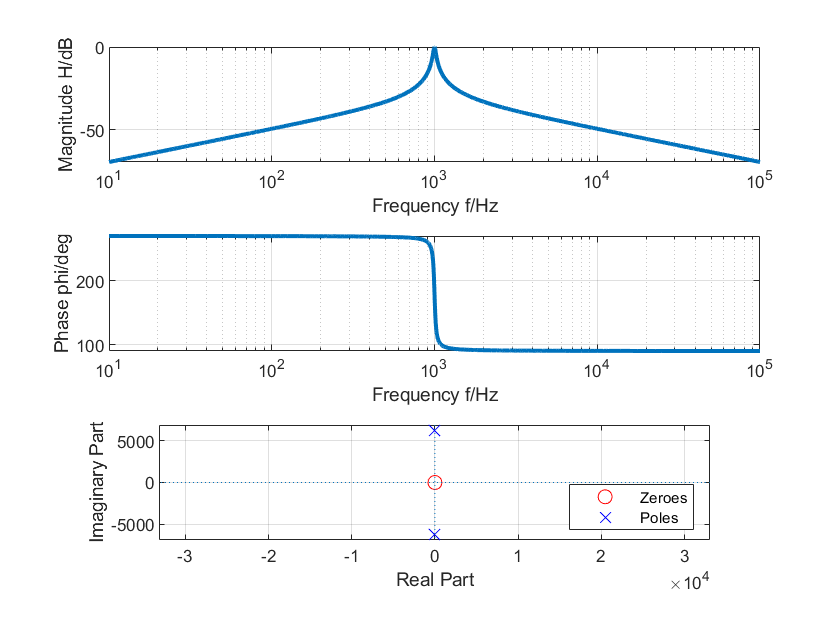

set(findobj (z1, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p1, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid

## **Band stop/Notch Filter Transfer Function from design equations of Tow-Thomas.**

num2= [b2 b1 b0];
den2 = [1 a1 a0];
H2 = tf(num2,den2);
% Plot bode diagram
[mag2, phase2] = bode(H2,ws);
db2=20*log10(mag2);
db2 = db2(:,:);
phase2 = phase2(:,:);
% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'Notch Filter Magnitude and Phase Response');
subplot(3,1,1);
semilogx(fs,db2,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase2,'linewidth',2);
grid on;
xlabel('Frequency f/Hz')
ylabel('Phase phi/deg')
subplot(3,1,3);
[z2,p2,~] = tf2zp(num2,den2)

z2 = 	1.0e+03 *

   0.0000 + 6.2832i
   0.0000 - 6.2832i


p2 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z2,p2,~] = zplane(z2,p2)

z2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: [0 0]
              YData: [6.2832e+03 -6.2832e+03]
              ZData: [1×0 double]

  Show all properties


p2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


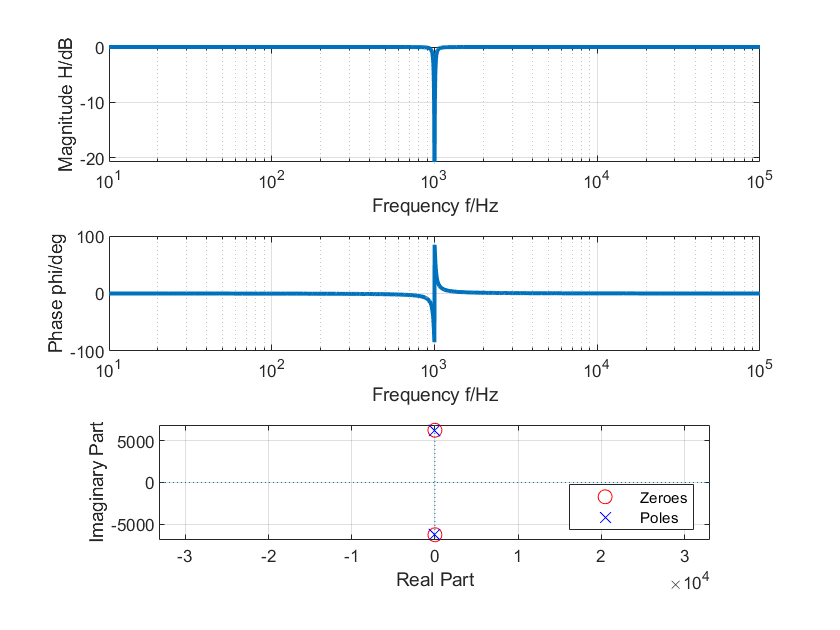

set(findobj (z2, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p2, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid

## ** Low-Pass Filter Transfer Function from design equations of Tow Thomas.**

num3 = [((b0-b2*a0)/(a0^0.5)) ((a1*b0-a0*b1)/(a0^0.5))];
den3 = [(-k1)*1 (-k1)*a1 (-k1)*a0];
H3 = tf(num3,den3);
% Plot bode diagram
[mag3, phase3] = bode(H3,ws);
db3 = 20*log10(mag3);
db3 = db3(:,:);
phase3 = phase3(:,:);
% Generate the magnitude plot and phase
figure('NumberTitle', 'off', 'Name', 'LowPass Filter Magnitude and Phase Response');
subplot(3,1,1);
semilogx(fs,db3,'linewidth',2);
grid on;
xlabel('Frequency f/Hz');
ylabel('Magnitude H/dB');
subplot(3,1,2);
semilogx(fs,phase3,'linewidth',2);
grid on;
xlabel('Frequency f/Hz')
ylabel('Phase phi/deg');
subplot(3,1,3);
[z3,p3,~] = tf2zp(num3,den3)


z3 =

  0×1 empty double column vector



p3 = 	1.0e+03 *

  -0.1047 + 6.2823i
  -0.1047 - 6.2823i


[z3,p3,~] = zplane(z3,p3)

z3 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 7
    MarkerFaceColor: 'none'
              XData: NaN
              YData: 0
              ZData: [1×0 double]

  Show all properties


p3 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [-104.7198 -104.7198]
              YData: [6.2823e+03 -6.2823e+03]
              ZData: [1×0 double]

  Show all properties


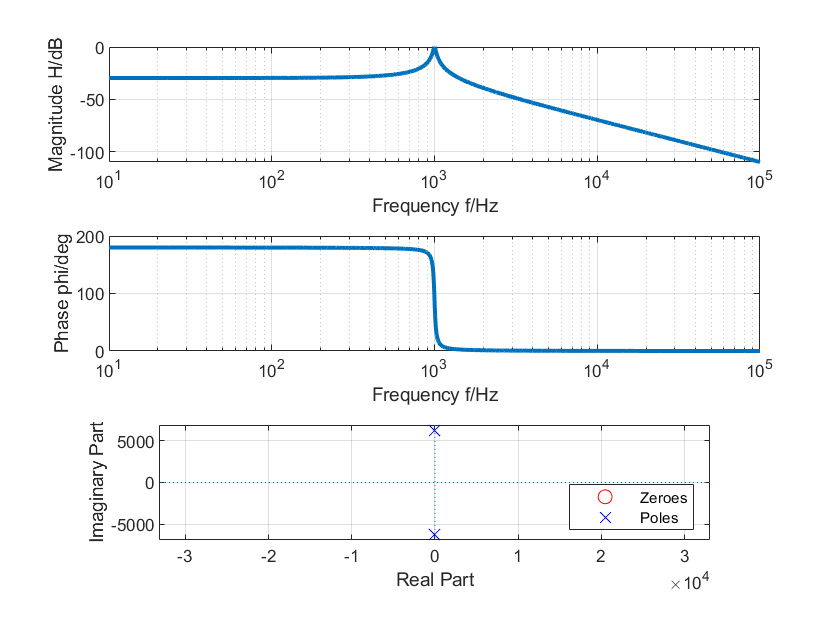

set(findobj (z3, 'Type' , 'line' ), 'Color' , 'r' );
set(findobj (p3, 'Type' , 'line' ), 'Color' , 'b' );
legend('Zeroes','Poles','Location','southeast'), grid